# Testatarbeit: Tunable Bandpass Filter for Embedded Devices

DSVB Part 1, HSLU-T&A, WaJ

close all;
clear all;
clc;

## 1. Parameter definition and verification 

Primary parameters for IIR and FIR filter design:

f_L = 290e3;    % lower band edge frequency [Hz]
f_U = 305e3;    % upper band edge frequency [Hz]
f_S = 2e6;      % sampling frequency for digital filters [Hz]
N1 = 4;        % FIR filter order (for same # of mult as 2nd order FIR)         <<<=== To be determined
N2 = 94;       % FIR filter order (for equivalent ampl. resp. as IIR filter)    <<<=== To be determined
N3 = 94;       %FIR filter order with Blackman (for equivalent ampl. resp. as IIR filter)  custom blackman implementation
N4 = 94;       %FIR filter order with Blackman (for equivalent ampl. resp. as IIR filter)  custom blackman implementation, Matlab implementation

Secondary parameters for plotting and analysis:

nfp = 500;       % # of frequency points used in plotting amplitude/phase responses

Verify parameter values:

if f_U <= f_L     error('Lower band edge frequency > upper frequency'); end
if f_L < 0        error('Lower band edge frequency < 0 Hz'); end
if f_U >= f_S/2   error('Upper band edge frequency > f_S/2'); end

Derived parameters:

B = f_U - f_L;                     % bandwidth of passband (frequencies above -3 dB attenuation)
f_0 = sqrt(f_L*f_U);               % center frequency of passband filter
Q = f_0/B;                         % filter quality factor
om_0 = 2*pi*f_0;                   % angular center frequency
f_vec = linspace(0, f_S/2, nfp);   % vector of frequency points between 0 and f_S/2 for plotting 
p_vec = 1i*2*pi*f_vec;             % vector of points on complex frequency axes to evaluate H(p)
A=1

A = 1

## 2. Analog Prototype Filter (Task 3a)

Define the continuous-time transfer function H(p) of the analog prototye filter by explicitly constructing the numerator and denominator poynomials using vector p_vec, and subsequenly element-wise division of these vectors.

% Formula 1 Assignment
b_p = A.*B./(f_0.*om_0).*p_vec;  
a_p = 1+B./(f_0.*om_0).*p_vec+1./om_0^2.*p_vec.^2;  
%by dividing f_U by f_S and multiplying it with 2pi, we map it on the
%unitcircle
%windowing design method, can be ignored
% wc2=2*pi*f_U/(f_S);
% wc1=2*pi*f_L/(f_S);
%for n!=0
% b=1./(pi.*[-N/2:N/2]).*(sin(wc2.*[-N/2:N/2])-(sin(wc1.*[-N/2:N/2])));
% b(N/2+1)=(wc2-wc1)/pi;
H_p = b_p ./ a_p;

Plot magnitude and phase response of the analog prototype filter in figure #1.

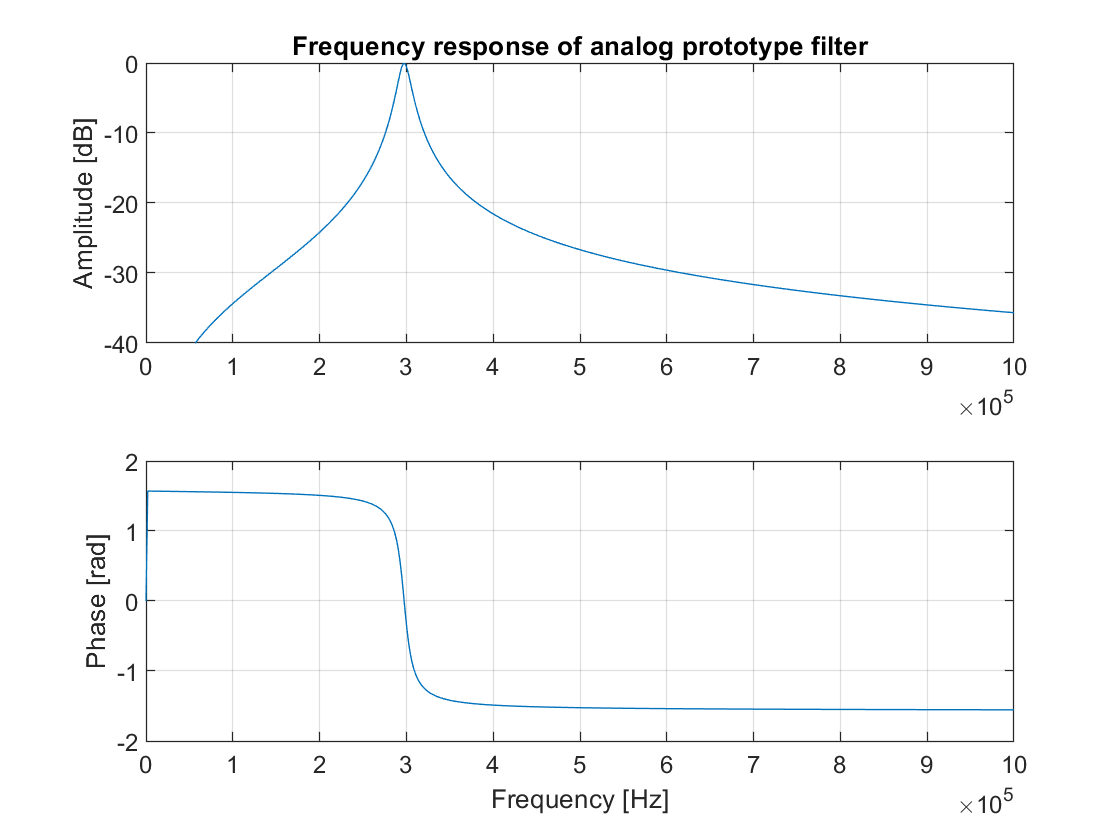

figure('name','figure 1')
subplot(2,1,1)
plot(f_vec,20*log10(abs(H_p)));
title('Frequency response of analog prototype filter')
ylabel('Amplitude [dB]')
axis([0 f_S/2 -40 0])
grid on;
subplot(2,1,2)
plot(f_vec,angle(H_p))
axis([0 f_S/2 -2 2])
grid on;
ylabel('Phase [rad]')
xlabel('Frequency [Hz]')

## 3. IIR Bandpass Filter (Task 3b)

Get the IIR filter coefficients using the bilinear transform of the analog prototype filter without and with prewarping.

[b_iir_nopw,a_iir_nopw,K_iir_nopw] = bp_iir_bilin(f_L, f_U, f_S, 'no prewarp'); %returns filtercoefficients and gain without prewarp
[b_iir_pw,a_iir_pw,K_iir_pw]       = bp_iir_bilin(f_L, f_U, f_S, 'prewarp');%returns filtercoefficients and gain with prewarp

Compute the frequency response of the two IIR filters at the same frequency points used for computing the frequency response of the analog prototype filter.

% returns frequency response, the third parameter defines the number of
% points necessary, so the scaling with 2*pi is not mandatory
% [H_iir_nopw] =freqz(K_iir_pw.*b_iir_nopw,a_iir_nopw,500);  
[H_iir_nopw] =freqz(K_iir_pw.*b_iir_nopw,a_iir_nopw,2*pi*f_vec/f_S);  
[H_iir_pw]   =freqz(K_iir_pw.*b_iir_pw,a_iir_pw,2*pi*f_vec/f_S) ;

Plot magnitude response of analog prototype filter, and two IIR filters designed with and without frequency prewarping in figure #2.

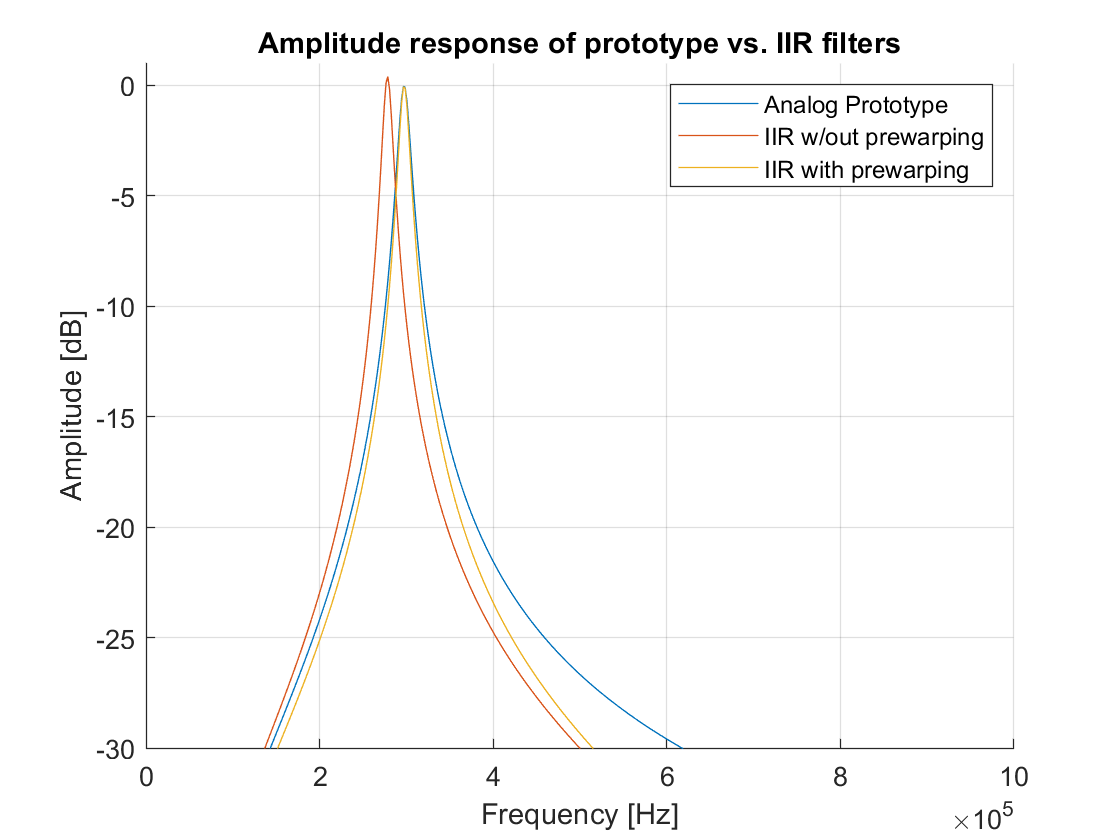

figure('name','figure 2')
hold on
plot(f_vec,20*log10(abs(H_p)));
plot(f_vec,20*log10(abs(H_iir_nopw)));
plot(f_vec,20*log10(abs(H_iir_pw)));
hold off
axis([0 f_S/2 -30 1])
grid on;
ylabel('Amplitude [dB]')
xlabel('Frequency [Hz]')
title('Amplitude response of prototype vs. IIR filters')
legend('Analog Prototype','IIR w/out prewarping','IIR with prewarping','Location','NorthEast')

%without prewarping omega_0 is at 276.6kHz,it should be at 296.6k which is
%a difference of 10k!!!!

## 4. FIR Bandpass Filter (Task 3c)

Get the FIR filter coefficients using the window design method with a rectangular window and two diffrent filter order:

b_fir_rect_N1=bp_fir_win(f_L, f_U, N1, f_S,'');%calls the function, writing 'blackman' for the last parameter should applay a blankmanwindow, 
b_fir_rect_N2=bp_fir_win(f_L, f_U, N2, f_S,'');
b_fir_rect_N3=bp_fir_win(f_L, f_U, N3, f_S,'blackman');
b_fir_rect_N4=bp_fir_win(f_L, f_U, N4, f_S,'');

Compute the frequency response of the two FIR filters at the same frequency points used for computing the frequency response of the IIR filters.

[H_fir_rect_N1] = freqz(b_fir_rect_N1,1,2*pi*f_vec/f_S); 
% [H_fir_rect_N1] = freqz(b_fir_rect_N1,1,500);
% [H_fir_rect_N2] = freqz(b_fir_rect_N2,1,500); 
[H_fir_rect_N2] = freqz(b_fir_rect_N2,1,2*pi*f_vec/f_S); 
[H_fir_rect_N3] = freqz(b_fir_rect_N3,1,2*pi*f_vec/f_S); 
[H_fir_rect_N4] = freqz(b_fir_rect_N4,1,2*pi*f_vec/f_S); 

Scale the frequency response such that the gain is 1 at the passband center frequency f_0. For this, first get gain of the current frequency response at the center frequency, and then divide the frequency response by this value.

% G1_f_0_custom = abs(H_fir_rect_N1(ceil(length(H_fir_rect_N1)/2)));  -> wrong
% we want to get value for frequency f_0. we have normalized it to fs/2,
% and have 500 values so we have to multiply it with that to get the actual
% value
G1_f_0 = abs(H_fir_rect_N1(round(nfp*2*f_0/f_S))); 
H_fir_rect_N1 = H_fir_rect_N1/G1_f_0;
% G2_f_0_custom = abs(H_fir_rect_N2(ceil(length(H_fir_rect_N2)/2))); ->
% wrong
G2_f_0= abs(H_fir_rect_N2(round(nfp*2*f_0/f_S))); 
H_fir_rect_N2 = H_fir_rect_N2/G2_f_0;

G3_f_0= abs(H_fir_rect_N3(round(nfp*2*f_0/f_S))); 
H_fir_rect_N3 = H_fir_rect_N3/G3_f_0;

G4_f_0= abs(H_fir_rect_N4(round(nfp*2*f_0/f_S))); 
H_fir_rect_N4 = H_fir_rect_N4/G4_f_0;

Plot magnitude response of the IIR filter obtained with prewarping together with the two FIR filters designed with the windowing methods and two different filter orders in figure #3.

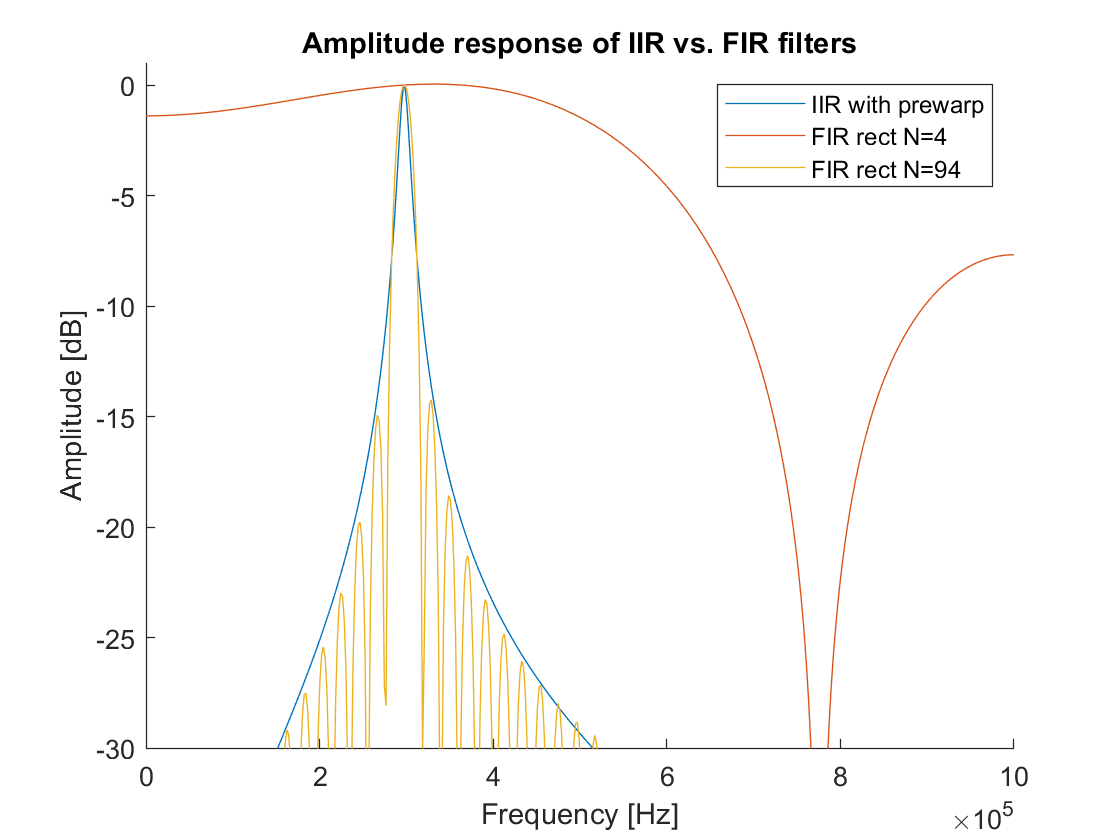


figure('name','figure 3')
hold on
plot(f_vec,20*log10(abs(H_iir_pw)));
plot(f_vec,20*log10(abs(H_fir_rect_N1)));
plot(f_vec,20*log10(abs(H_fir_rect_N2)));
hold off

axis([0 f_S/2 -30 1])
ylabel('Amplitude [dB]')
xlabel('Frequency [Hz]')
title('Amplitude response of IIR vs. FIR filters')
legend('IIR with prewarp',['FIR rect N=' num2str(N1)],['FIR rect N=' num2str(N2)],'Location','NorthEast')

# Optional:

The custom blackman implementation differs from the matlab implementation. We have checked our code and couldn't find the Reason.

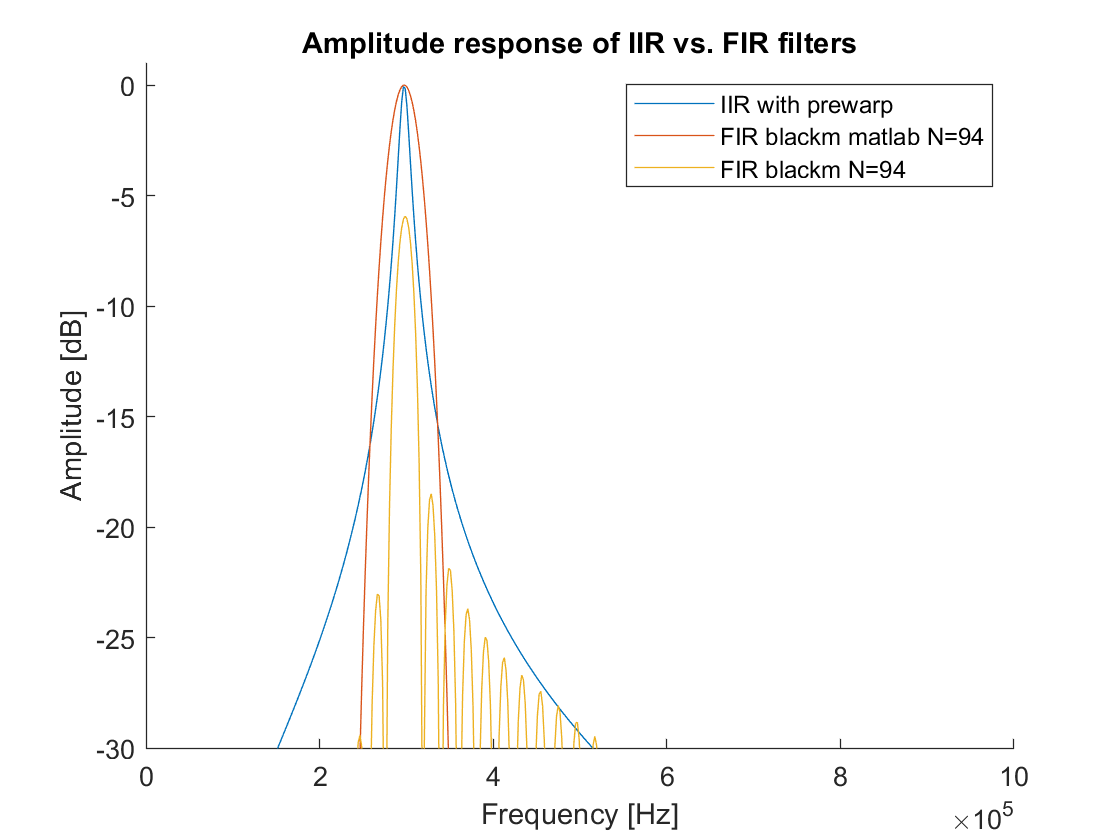

w=blackman(500);

figure('name','figure 3')
hold on
plot(f_vec,20*log10(abs(H_iir_pw)));
% plot(f_vec,20*log10(abs(H_fir_rect_N1)));
% plot(f_vec,20*log10(abs(H_fir_rect_N2)));
plot(f_vec,20*log10(abs(H_fir_rect_N3)));
plot(f_vec,20*log10(abs(w'.*H_fir_rect_N4)));
hold off

axis([0 f_S/2 -30 1])
ylabel('Amplitude [dB]')
xlabel('Frequency [Hz]')
title('Amplitude response of IIR vs. FIR filters')
legend('IIR with prewarp',['FIR blackm matlab N=' num2str(N3)],['FIR blackm N=' num2str(N4)],'Location','NorthEast')

# Notes: